fprintf("PLEASE SELECT AN IMAGE\n")

PLEASE SELECT AN IMAGE


i=uigetfile('*.*');
j=imread(i)

j = 320×640×3 uint8 array
j(:,:,1) =

     4     4     4     4     4     4     4     4     5     5     5     5     5     5     5     5     6     6     6     6     6     6     4     4     5     5     5     5     4     4     4     4     7     7     5     5     6     6     6     6     7     7     6     6     6     6     6     6     4     4    11    18    14     4     1     6     5     5     5     5     5     5     5     5     3     3     4     4     4     5     5     5     5     5     5     5     6     6     6     6     6     6     6     6     6     6     6     6     7     7     7     7     7     7     7     7     9     9     9     9     8     8     8     8     9     9     9     9     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     8     8     8     9     7     7     6     6     6     6     6     6     6     7     7     7     7     7     7     7     7     6     6     6     6     7     7     7     7     8     8     8     8     8     8     8     8  

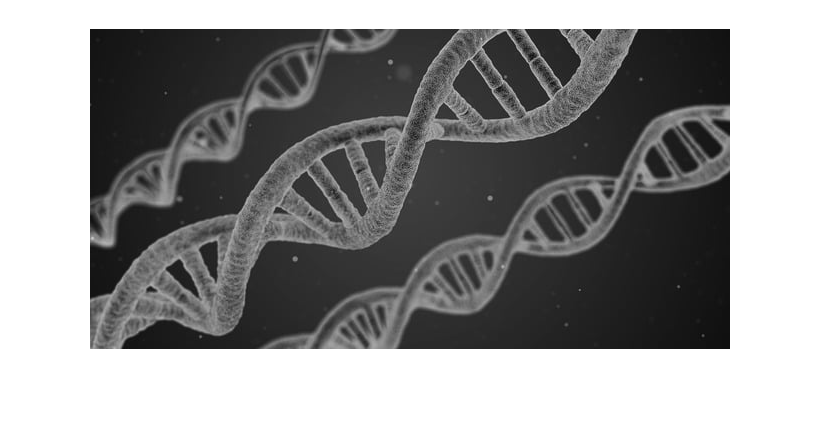

k=rgb2gray(j);
imshow(k)

[r,c]=size(k)

r = 320

c = 640

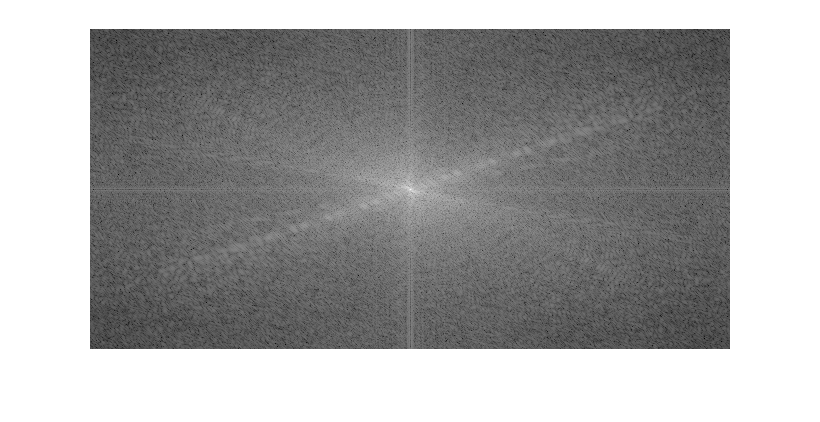

l=fft2(k);
m=fftshift(l);
n=abs(m);
o=log(1+n);
imshow(o,[]);

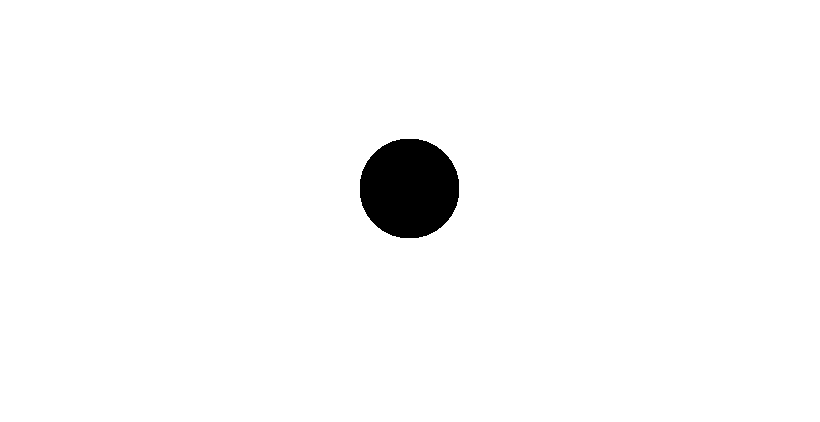

R=50;
x_c=0;
y_c=0;
[y,x]=ndgrid((-r/2)+1:r/2,(-c/2)+1:c/2);
Z= (x-x_c).^2+(y-y_c).^2 >= R^2;
imshow(Z)

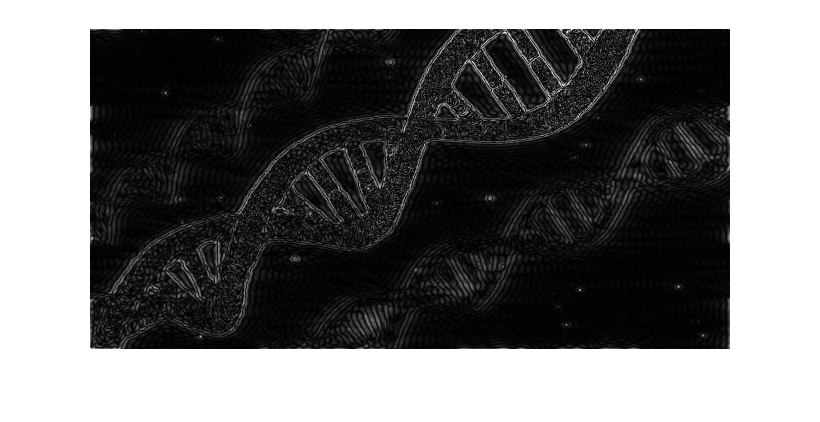

new=m.*Z;
new1=fftshift(new);
new2=ifft2(new1);
imshow(abs(new2),[]);

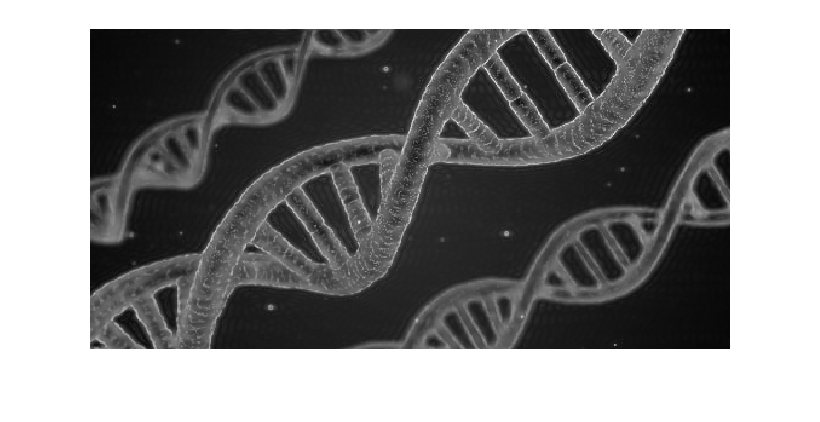

edge=abs(new2);
sharp=double(k)+edge;
imshow(sharp,[]);